Variational Gaussian Process

takes a mean function a kernel object and a list of inducing points

Training uses a mini-batch stochastic optimization.

clear all
%close all
clc

f1 = @(x) (6*x-2).^2.*sin(12*x-4);

xx = linspace(0,1,100)';
yy = f1(xx);

x1 = lhsdesign(500,1);
y1 = f1(x1);
y1 = y1 + normrnd(0,0*y1 + 0.8);

ma = means.const(2)+means.linear(6)

ma =   const with properties:

         meanz: {[1×1 means.const]  [1×1 means.linear]}
        coeffs: {[2]  [6]}
    operations: {'+'}


a = kernels.Matern52(1,0.2)*kernels.EQ(1,0.4).periodic(1,2) + kernels.RQ(0.1,0.3);

a.signn = 0.5;

Z = VGP(ma,a,linspace(0,1,5)');

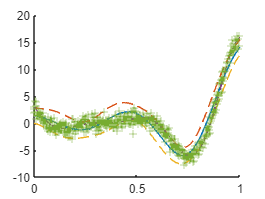

Z1 = Z.condition(x1,y1);

[ys,sig] = Z1.eval(xx);

figure
hold on
plot(xx,ys)
plot(xx,ys+2*sqrt(sig),'--')
plot(xx,ys-2*sqrt(sig),'--')
plot(xx,yy,'-.')
plot(x1,y1,'+')

tic
[Z2,LL] = Z1.train();

Variables (index) internally transformed to log coordinates: [3 4 5 6].
Beginning optimization of a STOCHASTIC objective fcn.

Optimization terminated: mesh size less than OPTIONS.TolMesh.
Estimated function value at minimum: 27.6928 +/- 0.508541 (mean +/- SEM from 10 samples).

Variables (index) internally transformed to log coordinates: [3 4 5 6].
Beginning optimization of a STOCHASTIC objective fcn.

Optimization terminated: mesh size less than OPTIONS.TolMesh.
Estimated function value at minimum: 25.9651 +/- 0.469149 (mean +/- SEM from 10 samples).

Variables (index) internally transformed to log coordinates: [3 4 5 6].
Beginning optimization of a STOCHASTIC objective fcn.

Optimization terminated: mesh size less than OPTIONS.TolMesh.
Estimated function value at minimum: 29.7077 +/- 1.61284 (mean +/- SEM from 10 samples).



toc

Elapsed time is 69.006165 seconds.


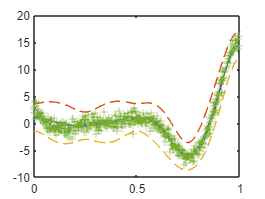

[ys,sig] = Z2.eval(xx);

figure
plot(xx,ys)
hold on
plot(xx,ys+2*sqrt(sig),'--')
plot(xx,ys-2*sqrt(sig),'--')
plot(xx,yy,'-.')
plot(x1,y1,'+')


for i = 1:5
    xn = bads(@(x) Z2.newXuDiff(x),rand(),0,1);
    Z2 = Z2.addInducingPoints(xn);
end

Beginning optimization of a DETERMINISTIC objective fcn.
 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2        -2.16083               1                              Uncertainty test
     0           3        -2.59404               1            Initial mesh      
     1           4         -5.3829               1         Successful poll      Train (failed)
     2           7        -7.33525               1    Successful search (ES-wcm)      
     2           8        -7.61608               1    Incremental search (ES-wcm)      
     2           9         -7.6974               1    Incremental search (ES-wcm)      
     2          10        -7.81477               1    Incremental search (ES-ell)      
     2          11        -7.81477             0.5             Refine grid      
     3          14        -8.78258             0.5    Successful search (ES-wcm)      
     3          15        -8.87641             0.5    Increment

Beginning optimization of a DETERMINISTIC objective fcn.
 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2       -0.641806               1                              Uncertainty test
     0           3        -2.64305               1            Initial mesh      
     1           4        -2.64305             0.5             Refine grid      Train (failed)
     2           7        -2.67792             0.5    Incremental search (ES-wcm)      
     2           8        -4.57697               1         Successful poll      
     3          12        -4.57697             0.5             Refine grid      
     4          15        -4.57697            0.25             Refine grid      
     5          19        -4.57697          0.0625             Refine grid      
     6          20        -4.57722          0.0625    Incremental search (ES-wcm)      

Optimization terminated: change in the function value less than OPTIONS.TolFun.
F

Beginning optimization of a DETERMINISTIC objective fcn.
 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2       -0.968876               1                              Uncertainty test
     0           3        -1.26886               1            Initial mesh      
     1           4        -2.76225               1         Successful poll      Train (failed)
     2           7        -3.35136               1    Incremental search (ES-wcm)      
     2           8        -3.35136             0.5             Refine grid      
     3           9        -3.37425             0.5    Incremental search (ES-wcm)      
     3          10        -3.37451             0.5    Incremental search (ES-wcm)      
     3          12        -3.37451            0.25             Refine grid      
     4          14        -3.40082            0.25    Incremental search (ES-wcm)      
     4          17        -3.40082           0.125             Refin

Beginning optimization of a DETERMINISTIC objective fcn.
 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2       -0.374504               1                              Uncertainty test
     0           3        -0.94834               1            Initial mesh      
     1           4        -1.02439             0.5             Refine grid      Train (failed)
     2           8        -1.02439            0.25             Refine grid      
     3          12        -1.02439           0.125             Refine grid      
     4          17        -1.02439         0.03125             Refine grid      

Optimization terminated: change in the function value less than OPTIONS.TolFun.
Function value at minimum: -1.02439.



Beginning optimization of a DETERMINISTIC objective fcn.
 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2        -0.35794               1                              Uncertainty test
     0           3       -0.753324               1            Initial mesh      
     1           4       -0.753324             0.5             Refine grid      Train (failed)
     2           5       -0.937643             0.5    Incremental search (ES-wcm)      
     2           6         -1.3875             0.5    Successful search (ES-wcm)      
     2           7        -1.45025             0.5    Incremental search (ES-wcm)      
     2           8        -1.46491             0.5    Incremental search (ES-wcm)      
     2           9        -1.47048             0.5    Incremental search (ES-wcm)      
     2          12        -1.47048            0.25             Refine grid      
     3          14        -1.48905            0.25    Incremen

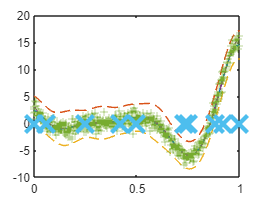


[ys,sig] = Z2.eval(xx);

figure
plot(xx,ys)
hold on
plot(xx,ys+2*sqrt(sig),'--')
plot(xx,ys-2*sqrt(sig),'--')
plot(xx,yy,'-.')
plot(x1,y1,'+')
plot(Z2.Xu,0*Z2.Xu,'x','MarkerSize',18,'LineWidth',3)

tic
[Z3,LL] = Z2.train();

Variables (index) internally transformed to log coordinates: [3 4 5 6].
Beginning optimization of a STOCHASTIC objective fcn.

Optimization terminated: mesh size less than OPTIONS.TolMesh.
Estimated function value at minimum: 27.522 +/- 1.97179 (mean +/- SEM from 10 samples).

Variables (index) internally transformed to log coordinates: [3 4 5 6].
Beginning optimization of a STOCHASTIC objective fcn.

Optimization terminated: mesh size less than OPTIONS.TolMesh.
Estimated function value at minimum: 25.7517 +/- 0.573864 (mean +/- SEM from 10 samples).

Variables (index) internally transformed to log coordinates: [3 4 5 6].
Beginning optimization of a STOCHASTIC objective fcn.

Optimization terminated: mesh size less than OPTIONS.TolMesh.
Estimated function value at minimum: 25.0669 +/- 0.810308 (mean +/- SEM from 10 samples).



toc

Elapsed time is 38.698017 seconds.


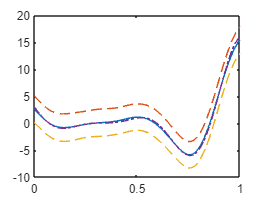


[ys,sig] = Z3.eval(xx);

figure
plot(xx,ys)
hold on
plot(xx,ys+2*sqrt(sig),'--')
plot(xx,ys-2*sqrt(sig),'--')
plot(xx,yy,'-.')